# 6 | COMMON STATISTICAL TEST

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 12-Jun-2024 15:17:42

## Set up the Import Options and import the data

clear global
clearvars
opts = spreadsheetImportOptions("NumVariables", 12);

% Specify sheet and range
opts.Sheet = "heart";
opts.DataRange = "A2:L919";

% Specify column names and types
opts.VariableNames = ["Age", "Sex", "ChestPainType", "RestingBP", "Cholesterol", "FastingBS", "RestingECG", "MaxHR", "ExerciseAngina", "Oldpeak", "ST_Slope", "HeartDisease"];
opts.VariableTypes = ["double", "categorical", "categorical", "double", "double", "double", "categorical", "double", "categorical", "double", "categorical", "categorical"];

% Specify variable properties
opts = setvaropts(opts, ["Sex", "ChestPainType", "RestingECG", "ExerciseAngina", "ST_Slope", "HeartDisease"], "EmptyFieldRule", "auto");

% Import the data
heart = readtable("/Users/juanheinklopper/Documents/MATLAB/MATLAB for Data Science/Data/heart.xlsx", opts, "UseExcel", false);
clear opts

## Introduction

In this final chapter we explore commonly used statistical tests and models. As in the previous chapter we start by importing the `heart.csv` spreadsheet file using the built-in app for data import.

We start with tests applicable to continuous numerical variables such as comparing two means.

## Common statistical tests for numerical variables

### Comparing the mean of a numerical variable grouped by the classes of a binary variable

Any data analysis starts with exploratory data analysis (EDA) in the form of summary statistics and data visualization. We use the `groupsummary` function to calculate summary statistics of the `Age` variable grouped by the two classes of the `Sex` variable.

% Compute group summary of Age observations grouped by classes of Sex
% variable
age_by_sex = groupsummary(heart,"Sex",["mean","median","mode","max","min", ...
    "range","std","var","nummissing"],"Age")

age_by_sex = 2×11 table
    Sex    GroupCount    mean_Age    median_Age    mode_Age    max_Age    min_Age    range_Age    std_Age    var_Age    nummissing_Age
    ___    __________    ________    __________    ________    _______    _______    _________    _______    _______    ______________

     F        193         52.492         53           54         76         30          46        9.5176     90.585           0       
     M        725         53.782         55           54         77         28          49        9.3979      88.32           0       


There is a small difference in the mean age of the two classes. Below we create column vectors separately for the ages of the two classes and assign the vectors to the variables `age_female` and `age_male`.

% Create an array of Age values for female subjects named "age_female"
age_female = table2array(heart(heart.Sex == "F", "Age"));
% Create an array of Age values for male subjects named "age_male"
age_male = table2array(heart(heart.Sex == "M", "Age"));

The difference between mean age for each group is calculated using simple subtraction.

% Calculate difference in means
mean(age_female) - mean(age_male)

ans = -1.2898

To compare the two age vectors we can use a $t$ test. There are two two-sample $t$ tests. The equal and the unequal variance $t$ tests. While there are statistical tests to determine equal variance, we use a simple variance fraction here. We divided the two variances. It does not matter which group is in the numerator and which is in the denominator.

% Variance ratio
var(age_female) / var(age_male)

ans = 1.0256

If the fraction is on the interval $\left[ \frac{1}{2},2 \right]$, we consider an equal variance $t$ test. Otherwise we use an unequal variance $t$ tests. In this case, we use the former. Before doing so, though, we complete the EDA and create a box-and-whisker plot of the age distribution of each of the classes of the `Sex` variable.

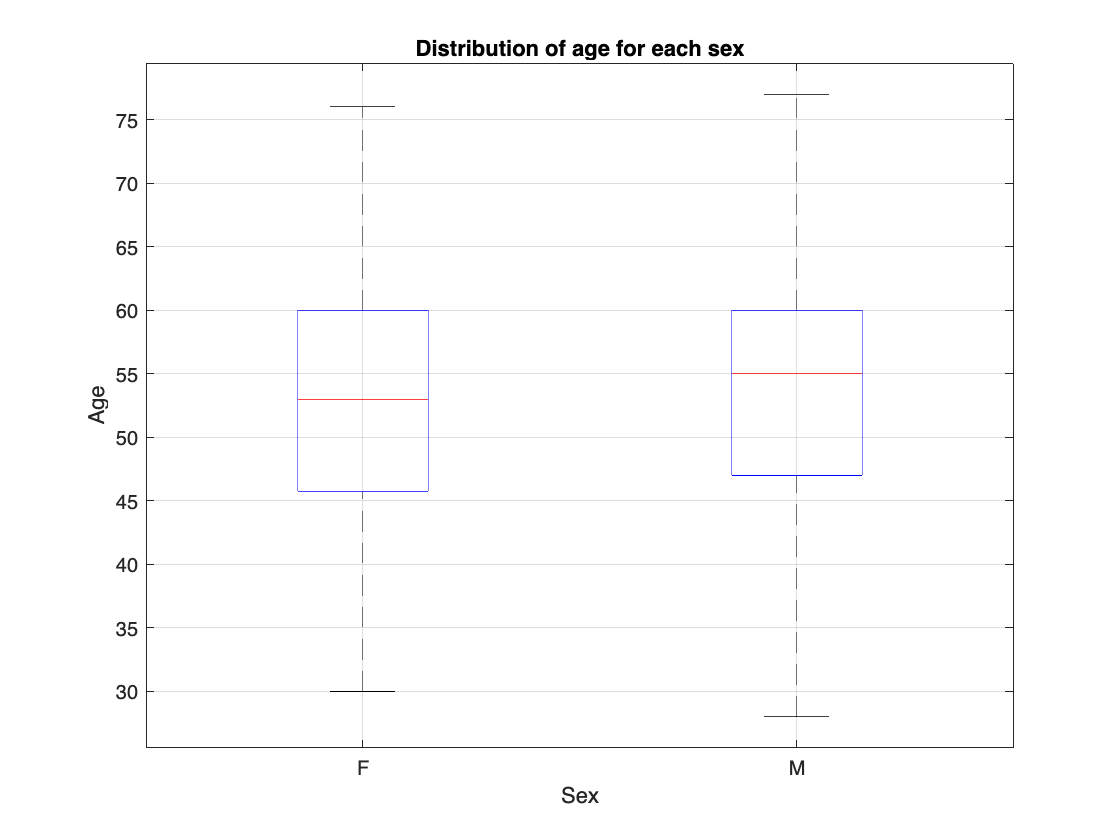

% Create a box plot of the Age variable for each of the classes in the Sex
% variable
boxplot(heart.Age, heart.Sex)
grid on
title("Distribution of age for each sex")
xlabel("Sex")
ylabel("Age")
hold off

From the summary statistics and the data visualization, it seems that there will not ne a difference between the mean ages. Below, we perform an equal variance $t$ test. The null hypothesis is that there is no difference between the mean ages in the population. We might write $H_{0}: \, \mu_{\text{female}} - \mu_{\text{male}} = 0$. The two-tailed alternative hypothesis states that there is a difference and we might write $H_{0}: \, \mu_{\text{female}} - \mu_{\text{male}} \ne 0$.

% Two-tailed equal variance t test at 5% level of significance (use
% 'Vartype','unequal' for unequal variance t-test)
[h, p, ci, stats] = ttest2(age_female,age_male, "Alpha", 0.05, "Tail", "both")

h = 0

p = 0.0914

ci =    -2.7878
    0.2081


stats = struct with fields:
    tstat: -1.6899
       df: 916
       sd: 9.4231


We see the result `h=0` and this means that we fail to reject the null hypothesis and we must state that there is not enough evidence at the $5\%$ level of significance to show that there is a difference in the mean age of women and men. We see a *p* value that is more than a chosen level of significance of $\alpha=0.05$. The confidence interval for the difference in means contains the value $0$ under the null hypothesis. All of these values indicate that we fail to reject the null hypothesis.

The results can be visualized for a better understanding, especially if we include out test statistic value $T$ and the critical $T$ value.. Under the null hypothesis or test statistic $T$ is described by the $t$ distribution given the degrees of freedom, which we write as $T \sim t \left( \nu \right)$ under $H_{0}$. We can calculate the latter for the $t$ test using the `df` attribute of our `stats` variable. Below, we assign this to the variable `nu`.

% Calculate the degrees of freedom
nu = stats.df

nu = 916

The results shows that $\nu = 916$. Next, we create a vector of values to populate the $x$ axis in our probability density plot. We create $300$ values on the interval $\left[ -5,5 \right]$ and assign it to the variable `k`.

% Create a vector of values to populate the x-axis
k = linspace(-5,5,300);

Now we use the vector of values in the variable `k` to calculate $y$ axis values representing the probability density function (PDF) of the $t$ distribution given $\nu$. For this we use the `tpdf` function. The PDF value are assigned to the variable `tdistpdf`.

% Calculate values for the PDF
tdistpdf = tpdf(k,nu);

The $T$ statistic for our test can be returned using the `tstat` attribute of our `stats` variable. We assign this to the variable `tval`.

% Return the test statistic and assign it to the variable tval
tval = stats.tstat

tval = -1.6899

The `tpdf` function can be used to calculate the value of the $T$ statistic for the given degrees of freedom. This is assigned to the variable `tvalpdf`. 

% Calculate the PDF for the given test statistic
tvalpdf = tpdf(tval,nu);

The (upper tail) critical value is calculated using the `tinv` function. The first argument is $1-\frac{\alpha}{2}$ and the second is the degrees of freedom.

% Calculate the upper tail critical value
tcrit = tinv(0.975,nu)

tcrit = 1.9626

We can now plot the PDF of the $t$ distribution under $916$ degrees of freedom. We draw vertical dashed lines at the critical values and note that the $T$ statistic is not in the upper or lower tails of rejection.

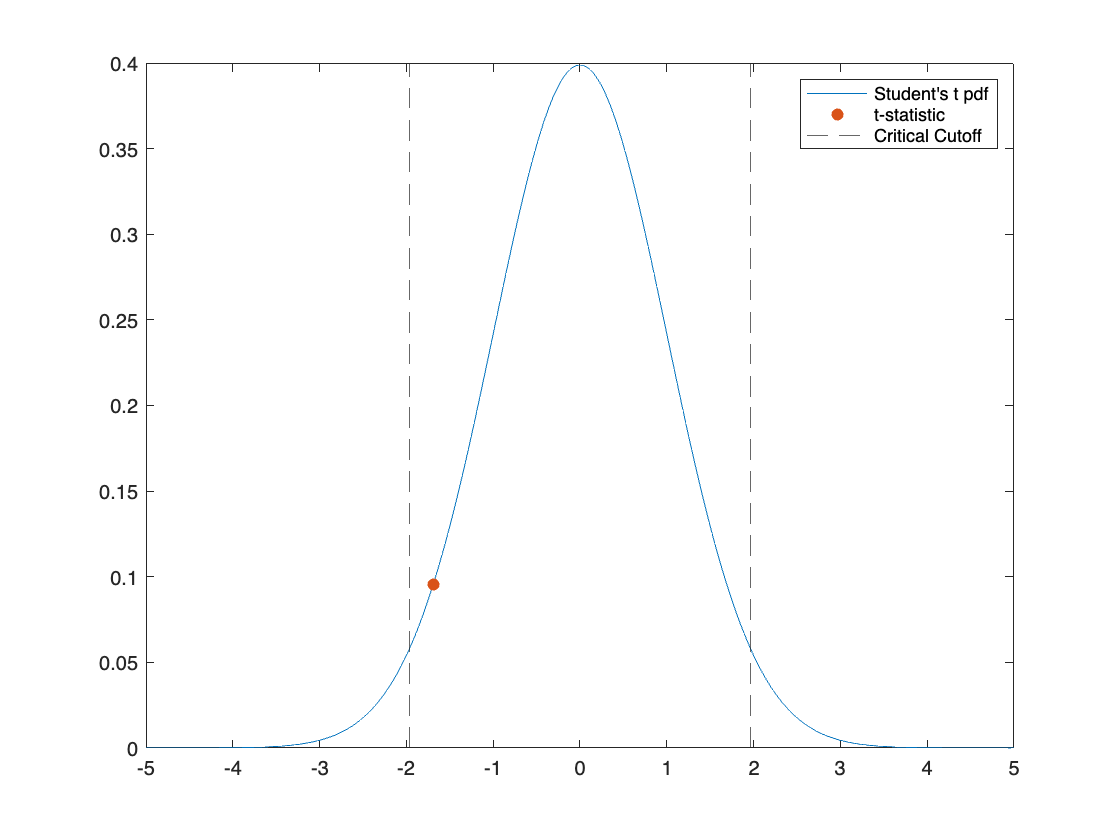

% Plot the PDF, the T statistic and the critical values
plot(k,tdistpdf)
hold on
scatter(tval,tvalpdf,"filled")
xline(tcrit,"--")
xline(-tcrit,"--")
legend(["Student's t pdf","t-statistic", ...
    "Critical Cutoff"])
hold off

Performing the $t$ test we assumed that the random variables were independent and identically distributed. In other words, we assumed that all subjects were independent of each other and assumed that the ages of both classes were from a population in which these values are normally distributed. Since we had at least $30$ samples in each group, these assumptions were not all critical and we could still invoke the Central Limit Theorem and use the probability density function of $t$ distribution to determine the distribution of $T$ statistic values under the null hypothesis and specific degrees of freedom.

There are statistical tests and data visualization that can be used to determine the assumption of normality. These include the Shapiro-Wilk tests and quantile-quantile plots or QQ plots. The latter plots the standard normal quantiles on the $x$ axis and the quantiles of the observations on the $y$ axis of a scatter plot. A line of normality is added. If the markers of the scatter plot fall roughly on this line, we assume that the values are from a population in which the variable is normally distributed. Below, we create QQ plots for both groups.

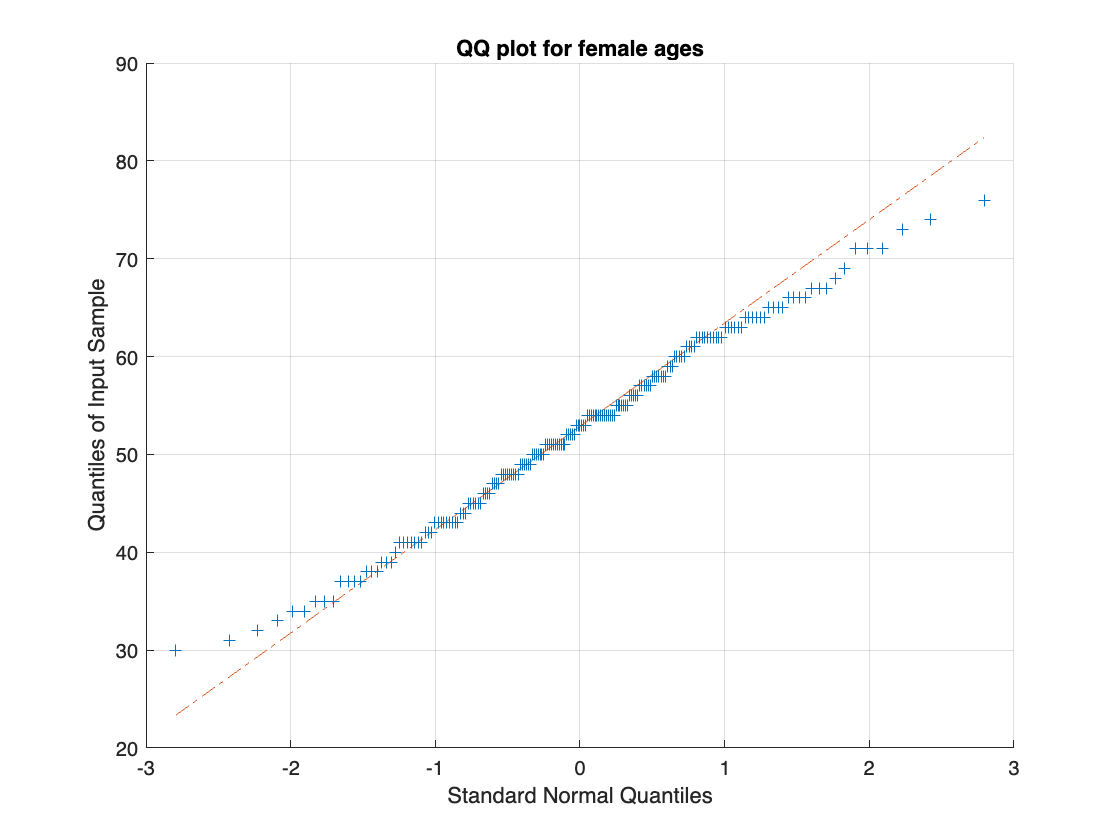

% Show QQ plots for female samples
qqplot(age_female)
grid on
title('QQ plot for female ages')
hold off

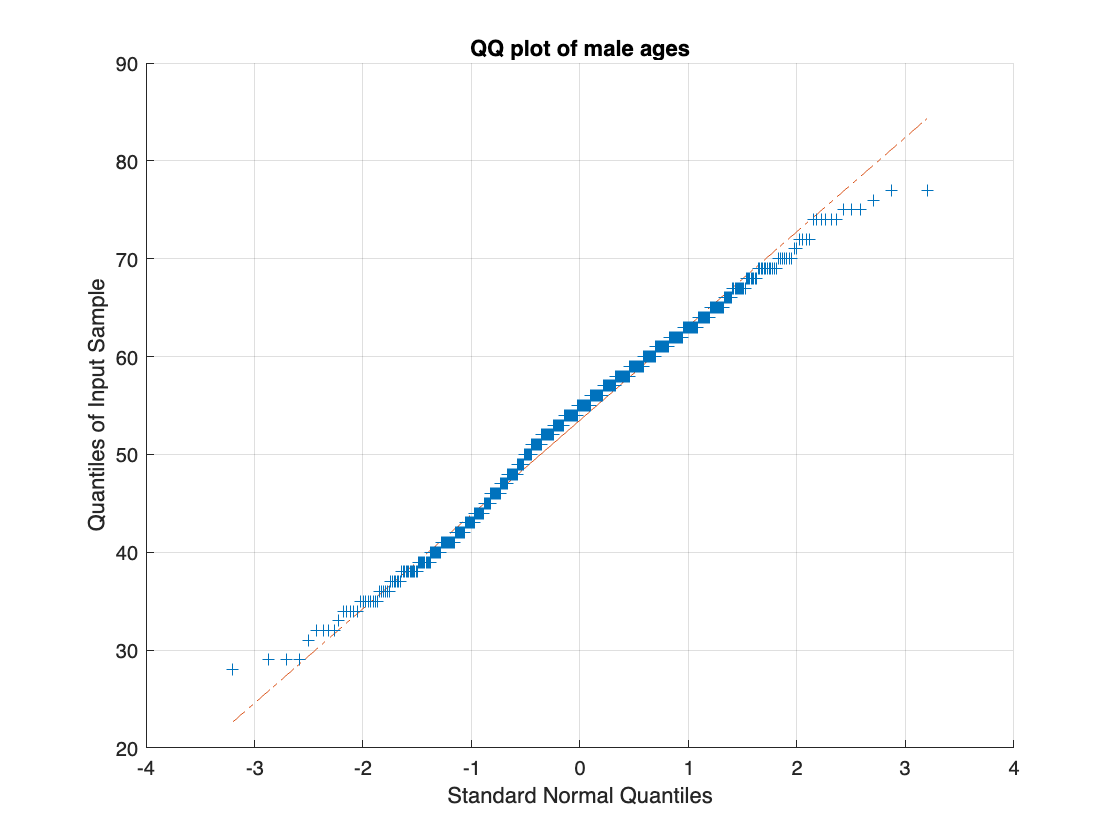

% QQQ plot of male ages
qqplot(age_male)
grid on
title('QQ plot of male ages')
hold off

In both cases it seems that we can assume normality. We should also verify that there are no significant statistical outliers. the box-and-whisker plot showed no suspected outliers. We could also use a rule of thumb such as looking for values that are more than $3$ standard deviations from the mean.

If the assumptions for the use of a parametric tests (such as the $t$ tests) are not met, we use a non-parametric tests such as the Mann-Whitney-U test. Under the null hypothesis of this test the medians are equal and under the alternative hypothesis, they are not. The `ranksum` test is used for the test.

% Compute Mann-Whitney-U test
[p, h, stats] = ranksum(age_female, age_male)

p = 0.0695

h = logical
   0


stats = struct with fields:
       zval: -1.8149
    ranksum: 82745


We find a similar result here and fail to reject the null hypothesis.

### Comparing the mean of a numerical variable grouped by the classes of a multi-level variable

We consider summary statistics and data visualization of the `Age` variable for each of the classes of the `ChestPainType` variable.

% Compute group summary
newTable = groupsummary(heart,"ChestPainType",["mean","median","max","min", ...
    "range","std","var"],"Age")

newTable = 4×9 table
    ChestPainType    GroupCount    mean_Age    median_Age    max_Age    min_Age    range_Age    std_Age    var_Age
    _____________    __________    ________    __________    _______    _______    _________    _______    _______

         ASY            496          54.96         56          77         31          46        8.7635     76.798 
         ATA            173         49.243         51          74         28          46        9.2598     85.743 
         NAP            203          53.31         53          76         33          43         9.608     92.314 
         TA              46         54.826         59          74         30          44        1

As part of our EDA we also create a box-and-whisker plot.

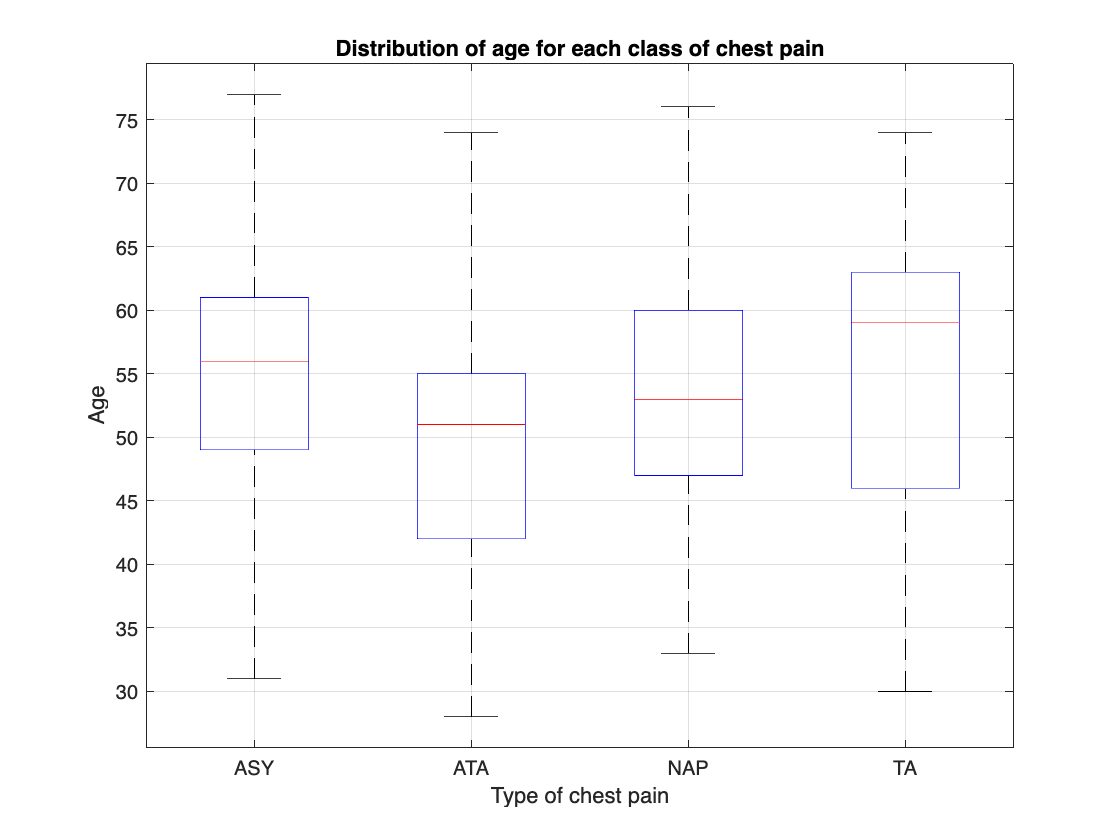

% Create a box plot of the Age variable for each of the classes in the
% ChestPainType variable
boxplot(heart.Age,heart.ChestPainType)
grid on
title("Distribution of age for each class of chest pain")
xlabel("Type of chest pain")
ylabel("Age")

Under the null hypothesis all population mean ages are equal. Under the alternative hypothesis, not all mean age are equal. To test this hypothesis, we can select a base class of the `ChestPainType` variable after constructing dummy variables for the variable. A linear model compares the ages for each group. We use the TASK button on the LIVE EDITOR tab and create a pivot table to see the classes of the `ChestPainType` variable and their frequencies.

% Create pivoted table
pivotedData = pivot(heart, Rows="ChestPainType", RowLabelPlacement="rownames")

pivotedData = 4×1 table
           count
           _____

    ASY     496 
    ATA     173 
    NAP     203 
    TA       46 


We now need to create a design matrix for the predictor variables and a vector for the response variable.

% Create a vector of the ChestPainType column and assign it to the variable chestPainType
chestPainType = heart.ChestPainType

chestPainType = 918×1 categorical array
     ATA 
     NAP 
     ATA 
     ASY 
     NAP 
     NAP 
     ATA 
     ATA 
     ASY 
     ATA 
     NAP 
     ATA 
     ATA 
     ASY 
     NAP 
     ATA 
     ASY 
     ATA 
     ASY 
     ATA 
     TA 
     ATA 
     ATA 
     ATA 
     NAP 
     NAP 
     ASY 
     ATA 
     ATA 
     ATA 


% Create dummy variables for a design matrix
dummyChestPainType = dummyvar(chestPainType)

dummyChestPainType =      0     1     0     0
     0     0     1     0
     0     1     0     0
     1     0     0     0
     0     0     1     0
     0     0     1     0
     0     1     0     0
     0     1     0     0
     1     0     0     0
     0     1     0     0


Take very careful note of the order of the dummy variables from the pivot table code above. The order can be rearranged as required, for instance setting the second column as the first would be `dummyChestPainType(:, [2 1 3 4])`. The base category must be the first column. The first column (the base class) is removed. The result is the final design matrix such that we have the linearity $\hat{\beta}_{0} + \hat{\beta}_{1} x_{1} + \hat{\beta}_{2} x_{2} + \hat{\beta}_{3} x_{3}$ Where $x_{1}$ is the `ATA` class, $x_{2}$ is the `NAP` class, and $x_{3}$ is the `TA` class.

% Remove the first column
dummyChestPainType = dummyChestPainType(:, [2 3 4])

dummyChestPainType =      1     0     0
     0     1     0
     1     0     0
     0     0     0
     0     1     0
     0     1     0
     1     0     0
     1     0     0
     0     0     0
     1     0     0


Now we extract a response vector, in this case the `Age` variable.

% Extract the Age column as a response vector assigned to the variable age
age = heart.Age

age =     40
    49
    37
    48
    54
    39
    45
    54
    37
    48


Now we can create a linear model using the `fitlm` function and assign the model to the variable `model`.

% Create a linear model assigned to the variable model
model = fitlm(dummyChestPainType, age)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate      SE         tStat        pValue  
                   ________    _______    _________    __________

    (Intercept)       54.96    0.41295       133.09             0
    x1              -5.7169    0.81207      -7.0399    3.7758e-12
    x2              -1.6493    0.76629      -2.1524       0.03163
    x3             -0.13359     1.4175    -0.094244       0.92494


Number of observations: 918, Error degrees of freedom: 914
Root Mean Squared Error: 9.2
R-squared: 0.0525,  Adjusted R-Squared: 0.0494
F-statistic vs. constant model: 16.9, p-value = 1.14e-10

Note that the intercept estimate is $54.96$. This is the mean age of the `ASY` chest pain type class. The $x1$ estimate is $-5.7169$ and if we calculate $54.96-5.7169$ we get the mean of the `ATA` class age. The intercept estimate plus any specific other estimate is the mean for the age of that class. This shows that the linear model is a comparison of the four mean ages.

We see a large $F$ statistic value of $16.9$ with a *p* value of less than $0.01$. We reject the null hypothesis and state that there is enough evidence at the $5\%$ level of significance to show that there is a difference in the mean age between the four groups of chest pain type. We can also use the `anova` function to see the results of analysis of variance for these results.

% Calculate ANOVA results
anova(model,'summary')

ans = 3×5 table
                SumSq     DF     MeanSq      F         pValue  
                ______    ___    ______    ______    __________

    Total        81589    917    88.974                        
    Model       4280.3      3    1426.8    16.868    1.1368e-10
    Residual     77309    914    84.583                        


From the ANOVA table we see the same $F$ statistic and *p* value. Note that the mean squared error due to the regression $1426.8$ and the mean squared error due to the residual is $84.5832$. We need to perform *post hoc* analysis to examine the pairwise differences in means. We have $k=4$ groups and can for $_{k}C_{2}= 6$ pairwise tests. There are many *post hoc* tests. Here we use the pairwise $t$ statistic and the Bonferroni adjusted *p* value. The latter divided the originally chosen $\alpha$ by the number of pairwise comparison so as not to compound the type I error. The adjusted *p* value is calculated below.

% Bonferroni alpha value
0.05/6

ans = 0.0083

We create a function to calculate the $t$ statistic.

% Pairwise t statistic
function t = pairwise_t(x1, x2, n1, n2, sse)
    t = (x1 - x2) / (sqrt((sse) * ((1/n1) + (1/n2))));
end

The sum of squared errors due to the residual is assigned to the variable `sw`.

% Assign the mean squared error due to the residual to the variable sw
sw = 84.5832

sw = 84.5832

The mean age of those with chest pain class `ASY` is compared to those with the class `ATA`.

% Calculate the t statistic for the first pairwise comparison
pairwise_t(54.9597, 49.2428, 496, 173, sw)

ans = 7.0399

The degrees of freedom is the sample size minus the number of groups, i.e. $N-k=918-4=914$. This is used to calculate the critical $t$ value.

% Calculate the critical t value
tinv(1-(0.0083/2),914)

ans = 2.6454

The first $t$ statistic is larger than the critical value and we reject the null hypothesis. There is a difference in the mean age between these two classes. The *p* value for the $t$ statistic is calculated.

% Calculate the two-tailed p value
2 * (1-tcdf(7.0399, 914))

ans = 3.7770e-12

Note that there are functions in MATLAB to conduct an analysis of variance test to compare the means of a numerical variable across more than two groups. The `anova1` function requires each group to have the same sample size, though. Instead, we used a linear regression model above, which is the same task. We can also use a non-parametric test such as the Kruskal-Wallis test. For the Kruskal-Wallist test we have that $H_{0}$: all medians are the same, and $H_{1}$: all medians are not the same. Below, we create four separate arrays to hold the `Age` variable values for each of the four classes of the `ChestPainType` variable.

% Create vectors of age values for each group
age_ASY = table2array(heart(heart.ChestPainType=='ASY',"Age"));
age_ATA = table2array(heart(heart.ChestPainType=='ATA',"Age"));
age_NAP = table2array(heart(heart.ChestPainType=='NAP',"Age"));
age_TA = table2array(heart(heart.ChestPainType=='TA',"Age"));

The `kruskalwallis` function performs the Kruskal-Wallis test. The first argument creates a table of columns where each column is an array of the ages for a specific group. The second is an array that generates a group name for each observation in each group. The `repelem` function is used to repeat the name of each group. Note the use of the `'` to transpose the output of each `repelem` function, which returns a row vector by default. The `kruskalwallis` function returns three objects, which we assign to the variables `p_kw` (returns a *p* value), `tbl_kw` (returns an analysis of variance table), and `stats_hw` (returns a statistics object that we can use for *post-hoc* analysis). The last argument is `"on"` which prints the results as output.

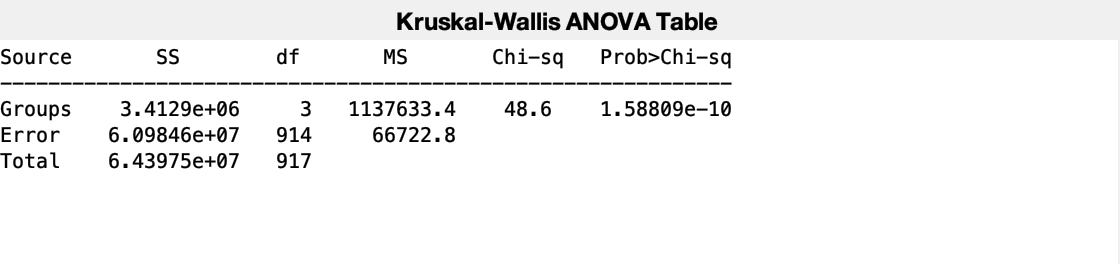

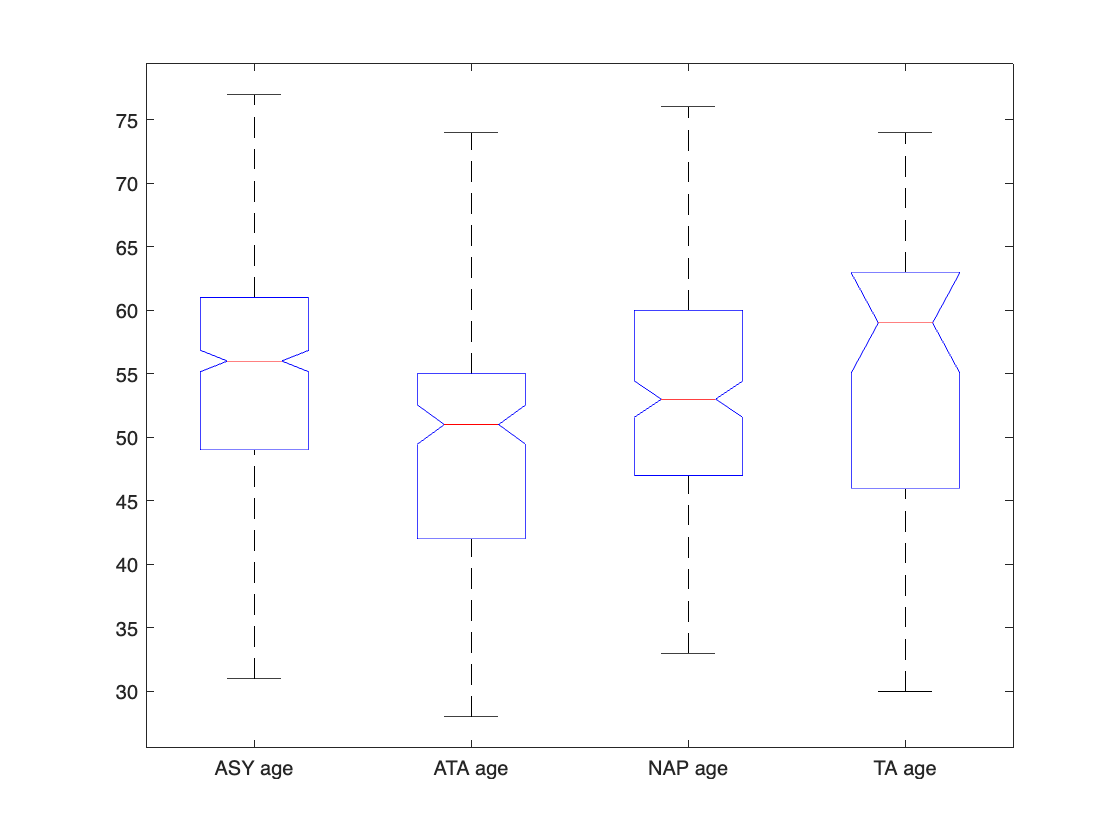

p_kw = 1.5881e-10

tbl_kw = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'        }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[3.4129e+06]}    {[  3]}    {[1.1376e+06]}    {[ 48.5986]}    {[ 1.5881e-10]}
    {'Error' }    {[6.0985e+07]}    {[914]}    {[6.6723e+04]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[  64397522]}    {[917]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats_kw = struct with fields:
       gnames: {4×1 cell}
            n: [496 173 203 46]
       source: 'kruskalwallis'
    meanranks: [500.5373 342.1705 445.9163 518.2174]
         sumt: 849450


% Perform the Kruskal-Wallis test
[p_kw, tbl_kw, stats_kw] = kruskalwallis([age_ASY;age_ATA;age_NAP;age_TA],[repelem("ASY age", length(age_ASY))'; repelem("ATA age", length(age_ATA))'; repelem("NAP age", length(age_NAP))'; repelem("TA age", length(age_TA))'],"on")

From the box-and-whisker plot is seems that the `ATA` group ages are different from all three other groups, but that they, in turn, are all very similar. The results show a *p* value that is less than a level of significance of $0.05$ and we state that there is enough evidence at the $5\%$ level of significance to show that there is a difference in the mean ages between the four chest pain types. We can now conduct *post-hoc* analysis.

The `multcompare` function can perform the analysis. We use it below with the first argument being the `stats_kw` objects from the Kruskal-Wallis test. By default, the critical value type is from Tukey's honestly significant difference procedure. Instead, we use the Bonferroni procedure here. Four object are returned. We assign them to the variables `c_b` (returns a matrix of pairwise comparison results), `m_b` (returns the estimated values of the means (or whatever statistics are being compared) for each group and the corresponding standard errors), `h_b` (returns a handle for the comparison graph), and `gnames_b` (returns the groups names). By default, the first group is used as the control group. The `ControlGroup` argument can be used to select a different groups as control.

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


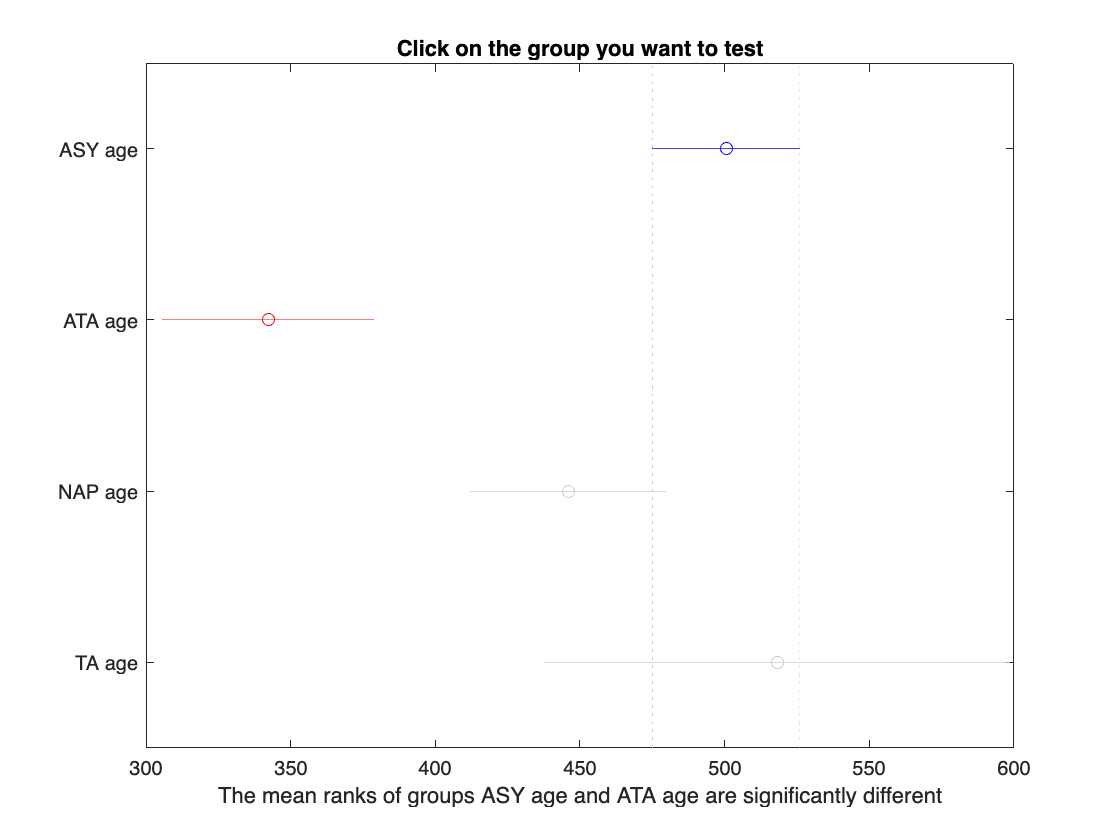

% Perform a multi-comparison test
[c_b, m_b, h_b, gnames_b] = multcompare(stats_kw,'CriticalValueType','bonferroni');

The plot is not that helpful in determining all the pairwise comparisons. Below, we create a table to summarize the mean and standard error of the ages for each group.

% Print a summary of the mean and standard errors for the age of each
% group
tbl_summary = array2table(m_b,"RowNames",gnames_b,"VariableNames",["Mean","Standard Error"])

tbl_summary = 4×2 table
                Mean     Standard Error
               ______    ______________

    ASY age    500.54        11.899    
    ATA age    342.17        20.148    
    NAP age    445.92          18.6    
    TA age     518.22        39.072    


We can also print a summary of all six pairwise comparisons.

% Print a summary of the pairwise comparisons
tbl_pw = array2table(c_b,"VariableNames",["Group","Control Group","Lower Limit","Difference","Upper Limit","p-value"]);
tbl_pw.("Group") = gnames_b(tbl_pw.("Group"));
tbl_pw.("Control Group") = gnames_b(tbl_pw.("Control Group"))

tbl_pw = 6×6 table
       Group       Control Group    Lower Limit    Difference    Upper Limit     p-value  
    ___________    _____________    ___________    __________    ___________    __________

    {'ASY age'}     {'ATA age'}        96.634        158.37          220.1      7.8306e-11
    {'ASY age'}     {'NAP age'}       -3.6318        54.621         112.87        0.080216
    {'ASY age'}     {'TA age' }       -125.44        -17.68         90.077               1
    {'ATA age'}     {'NAP age'}       -176.09       -103.75        -31.404      0.00092771
    {'ATA age'}     {'TA age' }       -292.03       -176.05        -60.066      0.00037275
    {'NAP age'}     {'TA age' }       -186.47       -72.301         41.866         0.56858


A suspected from the box-and-whisker plot, the significant differences are between the `ATA` group and all three other groups.

## Common tests for categorical variables

### Pearson's $\chi^{2}$ test for association between two categorical variables

Pearson's $\chi^{2}$ test for association requires a table of observed data (contingency table). We consider the `Sex` and `ChestPainType` variables. Under the null hypothesis there is no association between these two variables (the variables are independent).

% Create pivot table
sex_chestpaintype = pivot(heart, Rows="Sex", Columns="ChestPainType")

sex_chestpaintype = 2×5 table
    Sex    ASY    ATA    NAP    TA
    ___    ___    ___    ___    __

     F      70     60     53    10
     M     426    113    150    36


The table values as assigned to a matrix.

% Matrix of values
sex_chestpaintype_matrix = [70 60 53 10; 426 113 150 36]

sex_chestpaintype_matrix =     70    60    53    10
   426   113   150    36


We create a user-defined function named `chi2square` to conduct Pearson's $\chi^{2}$ test.

% Create a function to conduct the test at the 5% level of significance
function [e, df, h, p, X2, X2crit] = chi2square(x) % To return table of expected values, degrees of freedom, test decision rule, p value, X2 and critical X2 values
% Compute expectation and chi-square statistic, and determine p value.

    e = sum(x,2)*sum(x)/sum(x(:)); % Calculate the expected values (independent variables)
    X2 = (x-e).^2./e; % Calculate square of observed value value minus expected divided by expected value
    X2 = sum(X2(:)); % Sum over all
    df = prod(size(x)-[1 1]); % Calculate the degrees of freedom
    p = 1-chi2cdf(X2,df); % Calculate p value of X2 statistic
    X2crit = icdf('chisquare', [1 - 0.05], df); % Calculate critical X2 value
    h = double(p <= 0.05); % Decision rule based on p value
end
% Use table values as input
[e, df, h, p, X2, X2crit] = chi2square(sex_chestpaintype_matrix)

e =   104.2789   36.3715   42.6786    9.6710
  391.7211  136.6285  160.3214   36.3290


df = 3

h = 1

p = 4.8803e-08

X2 = 36.8792

X2crit = 7.8147

The table of observed data meets the size sample size assumption for the test. The `h=1` indicates that we reject the null hypothesis. The *p* value is less than the chosen $\alpha=0.05$. As confirmation we see that the $X^{2}$ test statistic is larger than the critical $X^{2}$ value for $3$ degrees of freedom. There is enough evidence at the $5\%$ level of significance to show that there is an association between the `Sex and ChestPainType variables.`

## Statistical models

### Correlation between two numerical variables

The linear association between two continuous numerical variables can be evaluated using correlation. A scatter plot shows the correlation between the `Age` and `Cholesterol` variables.

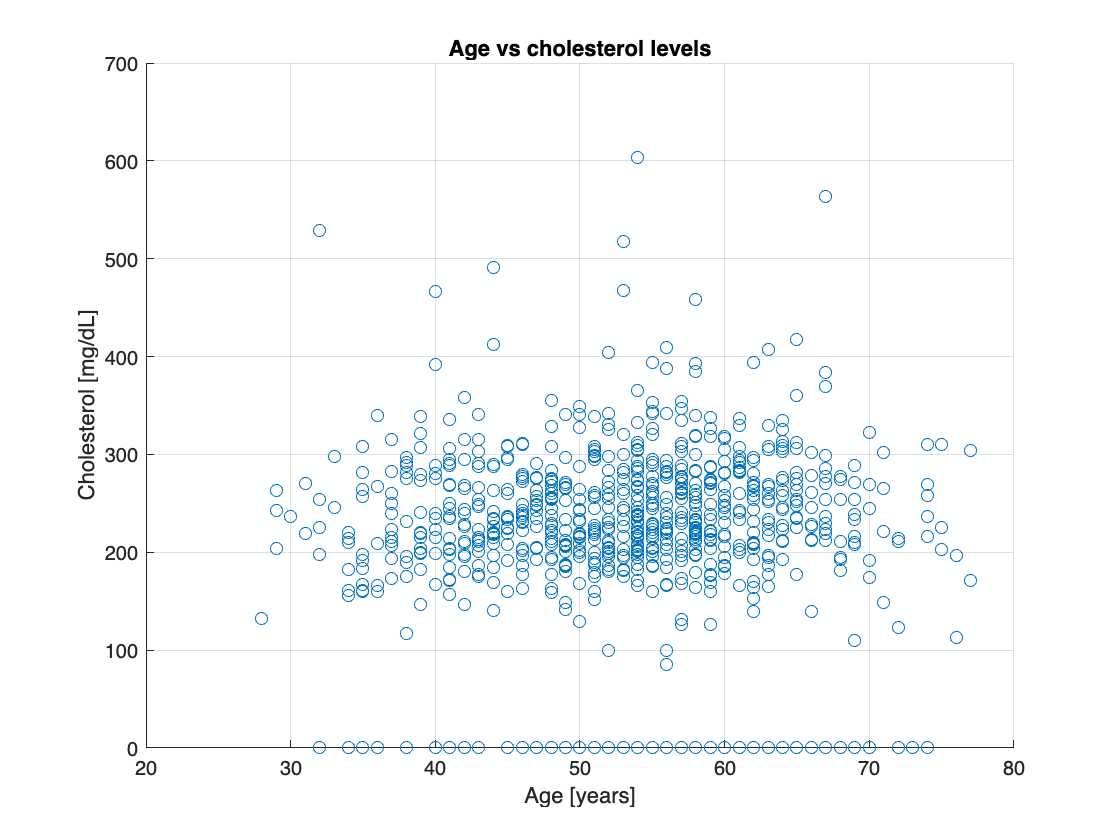

% Create a scatter plot of Age vs Cholesterol
scatter(heart.Age,heart.Cholesterol)
grid on
title("Age vs cholesterol levels")
xlabel("Age [years]")
ylabel("Cholesterol [mg/dL]")
hold off

We note all the values in the `Cholesterol` variable that are $0$. A new table is created for the two variables and all observations that are $0$ are omitted.

% Create a new table
age_cholesterol_sex_data = heart(heart.Cholesterol ~= 0,{'Age', 'Cholesterol','Sex'})

age_cholesterol_sex_data = 746×3 table
    Age    Cholesterol    Sex
    ___    ___________    ___

    40         289         M 
    49         180         F 
    37         283         M 
    48         214         F 
    54         195         M 
    39         339         M 
    45         237         F 
    54         208         M 
    37         207         M 
    48         284         F 
    37         211         F 
    58         164         M 
    39         204         M 
    49         234         M 
    42         211         F 
    54         273         F 


The scatter plot is recreated.

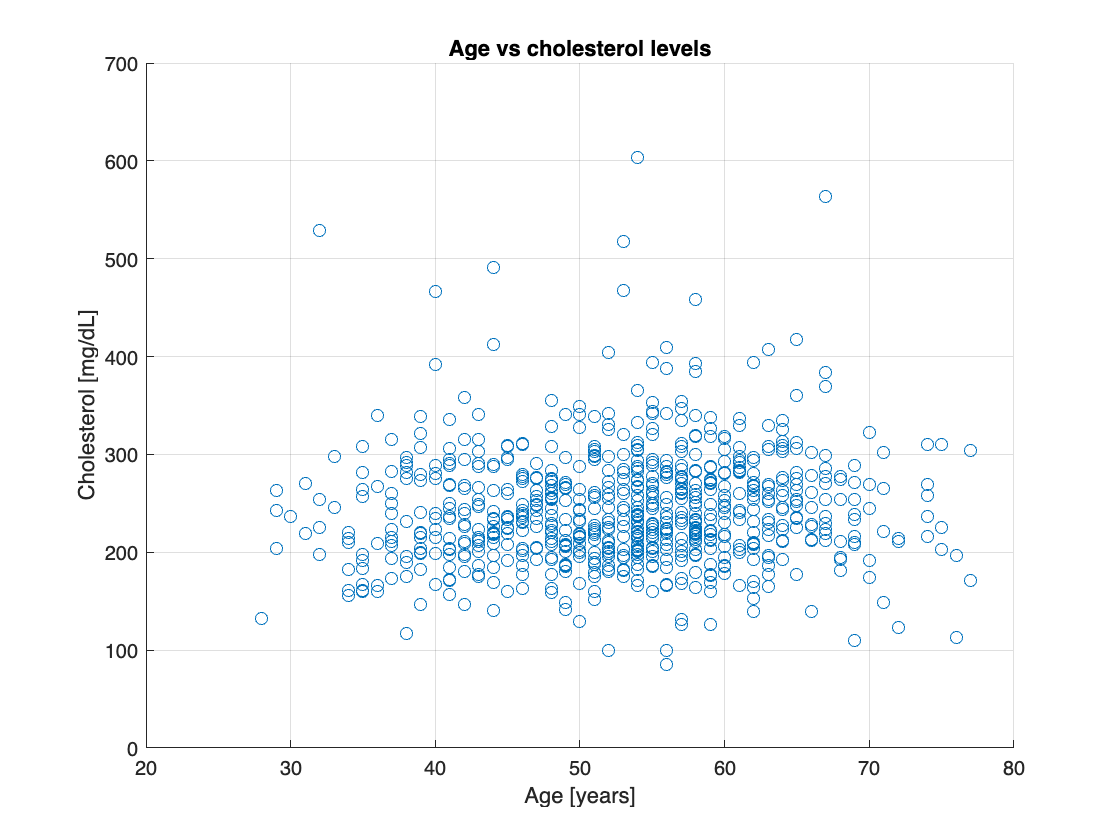

% Create a scatter plot of Age vs Cholesterol
scatter(age_cholesterol_sex_data.Age, age_cholesterol_sex_data.Cholesterol)
grid on
title("Age vs cholesterol levels")
xlabel("Age [years]")
ylabel("Cholesterol [mg/dL]")
hold off

The `corr` function returns Pearson's correlation coefficient $r$ and the *p* value.

% Correlation between Age and Cholesterol variables
[rho, pval] = corr(age_cholesterol_sex_data.Age, age_cholesterol_sex_data.Cholesterol, "Tail", "both")

rho = 0.0588

pval = 0.1088

There is poor linear association (or correlation) between the two variables.

### Linear regression

We use the Curve Fitter app in the APPS tab. The model can be exported to the workspace and the plots can be opened in the Plot Editor. We create two vectors to use in the app.

% Create vectors
age = age_cholesterol_sex_data.Age;
cholesterol = age_cholesterol_sex_data.Cholesterol;

We create the model using the app. The app returns a named model to the workspace.

The `fitlm` function can be used to create the model manually/

% Create a linear model
age_cholesterol_model = fitlm(age, cholesterol, "linear")

age_cholesterol_model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)      225.3      12.236    18.412    1.1457e-62
    x1             0.36564     0.22775    1.6055       0.10881


Number of observations: 746, Error degrees of freedom: 744
Root Mean Squared Error: 59.1
R-squared: 0.00345,  Adjusted R-Squared: 0.00211
F-statistic vs. constant model: 2.58, p-value = 0.109

The model $\hat{y} = \hat{\beta}_{0} + \hat{\beta}_{1} x = 225.3 + 0.36564 \times \text{age}$.

The results are the same as for the Curve Fitter app. The $F$ statistic is $0.258$ with a *p* value of $0.109$. The coefficient of determination is a low $0.00345$ meaning that the model explains less than $0.3\%$ of the variability in the cholesterol value.

% Create vectors
sex = categorical(age_cholesterol_sex_data.Sex);
sex(1:5)

ans = 5×1 categorical array
     M 
     F 
     M 
     F 
     M 


We add another explanatory variable, `Sex`. This is a binary variable and we choose `M` as the base class.

% Create dummy variables for a design matrix
dummySex = dummyvar(sex);
% Create a design matrix
X = [age dummySex]

X =     40     0     1
    49     1     0
    37     0     1
    48     1     0
    54     0     1
    39     0     1
    45     1     0
    54     0     1
    37     0     1
    48     1     0


% Create design matrix choosing columns 1 and 2 (by choosing column 2 we
% have M as the base class
X = X(:, [1 2]);
% Fit a model with two predictor variable (numerical and binary)
fittedmodel_age_sex_cholesterol = fitlm(X, cholesterol, 'linear')

fittedmodel_age_sex_cholesterol = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     220.14      12.291    17.911    6.5791e-60
    x1             0.39356     0.22671    1.7359      0.082991
    x2               15.09      5.0147    3.0092     0.0027079


Number of observations: 746, Error degrees of freedom: 743
Root Mean Squared Error: 58.8
R-squared: 0.0155,  Adjusted R-Squared: 0.0128
F-statistic vs. constant model: 5.83, p-value = 0.00307

### Logistic regression

If the outcome variable is binary, we can create logistic regression model.

X = dummySex;
X = X(:, 1);
glm_data = table(X, age, cholesterol,'VariableNames',{'Sex', 'Age', 'Cholesterol'})

glm_data = 746×3 table
    Sex    Age    Cholesterol
    ___    ___    ___________

     0     40         289    
     1     49         180    
     0     37         283    
     1     48         214    
     0     54         195    
     0     39         339    
     1     45         237    
     0     54         208    
     0     37         207    
     1     48         284    
     1     37         211    
     0     58         164    
     0     39         204    
     0     49         234    
     1     42         211    
     1     54         273    


% Create a logistic regression model
predict_sex = fitglm(glm_data, 'Sex ~ Age + Cholesterol', 'Distribution', 'binomial')

predict_sex = Generalized linear regression model:
    logit(Sex) ~ 1 + Age + Cholesterol
    Distribution = Binomial

Estimated Coefficients:
                   Estimate        SE         tStat      pValue  
                   _________    _________    _______    _________

    (Intercept)      -1.5353      0.57776    -2.6574    0.0078753
    Age            -0.011775    0.0090923    -1.2951      0.19529
    Cholesterol    0.0041299    0.0014002     2.9494    0.0031834


746 observations, 743 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 9.91, p-value = 0.00705

The estimates, $\hat{\beta}_{1}$ and $\hat{\beta}_{2}$, of the model are log odds ratios and we have to calculate $e^{\hat{\beta}_{i}}$ to write the model.

% Exponential each of the coefficients
exp(predict_sex.Coefficients.Estimate)

ans =     0.2154
    0.9883
    1.0041
